close all
clear
clc

syms x y t r phi z real
syms e n beta mu_0 c omega real positive
syms pi

% Magnetic vector potential (without limit of Bessel function)
Az=(-e)*mu_0/(2*pi)^2*...
   besselk(0,1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
   exp(-1i*omega/(beta*c)*z);

% % Magnetic vector potential (with limit of Bessel function)
% Az=(-e)*mu_0/(2*pi)^2*...
%    sqrt(pi/(2*omega/c*sqrt(n^2-beta^(-2))*r))*exp(-1i*pi/4)*exp(-1i*omega/c*sqrt(n^2-beta^(-2))*r)*...
%    exp(-1i*omega/(beta*c)*z);

% Derive electric field from the potentials
Er=simplify(-c/(n^2*beta)*diff(Az,r));
Ez=simplify(-1i*omega*Az-c/(n^2*beta)*diff(Az,z));

% Derive magnetic field from the potentials
Bpconj=simplify(-diff(conj(Az),r));
Hp=simplify(1/mu_0*conj(Bpconj));

% Assume r>0 to simplify the expressions
assume(r,'positive')

% Impose analytical solution
H= subs(Hp,[r,z],[abs(y),x]).*sign(y)

$$H = -\frac{e\,\omega \,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{4\,\beta \,c\,\pi^{2}}$$

E=[subs(Ez,[r,z],[abs(y),x])
   subs(Er,[r,z],[abs(y),x]).*sign(y)]

$$E = \left[\begin{array}{c} \frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,K_{0}\left(\frac{\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\left(\beta^{2}\,n^{2}\,\mathrm{i}-\mathrm{i}\right)}{4\,\beta^{2}\,n^{2}\,\pi^{2}}\\ -\frac{e\,\mu_{0}\,\omega \,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\omega \,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\beta \,c}\right)\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{4\,\beta^{2}\,n^{2}\,\pi^{2}} \end{array}\right]$$

j=[-e/(2*pi^2*abs(y))*dirac(y)*exp(-1i*omega/(beta*c)*x)
   0]

$$j = \left[\begin{array}{c} -\frac{e\,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\delta (y)}{2\,\pi^{2}\,\left|y\right|}\\ 0 \end{array}\right]$$

% Additional variables to compute residuals
X=[x,y];
epsilon_0=1/(c^2*mu_0);
mu=mu_0;
epsilon=n^2*epsilon_0;
assume(beta^2*n^2>1)
 
% Check residual of magnetic field
R_H=simplify(...
    1i*mu*omega*H...
    +mycurl(E,X))

$$R\_H = 0$$

% Check residual of electric field
% CONSIDER THAT Y/SIGN(Y)=ABS(Y) (OR Y*SIGN(Y)=ABS(Y))
R_E=simplify(...
    1i*epsilon*omega*E...
    -mycurl(H,X)...
    +j)

$$R\_E = \left[\begin{array}{c} -\frac{e\,\omega \,{\mathrm{e}}^{-\frac{\omega \,x\,\mathrm{i}}{\beta \,c}}\,\mathrm{sign}\left(y\right)\,K_{1}\left(\frac{\omega \,\left|y\right|\,\sqrt{1-\beta^{2}\,n^{2}}}{\beta \,c}\right)\,\sqrt{1-\beta^{2}\,n^{2}}}{4\,\beta \,c\,y\,\pi^{2}}\\ 0 \end{array}\right]$$

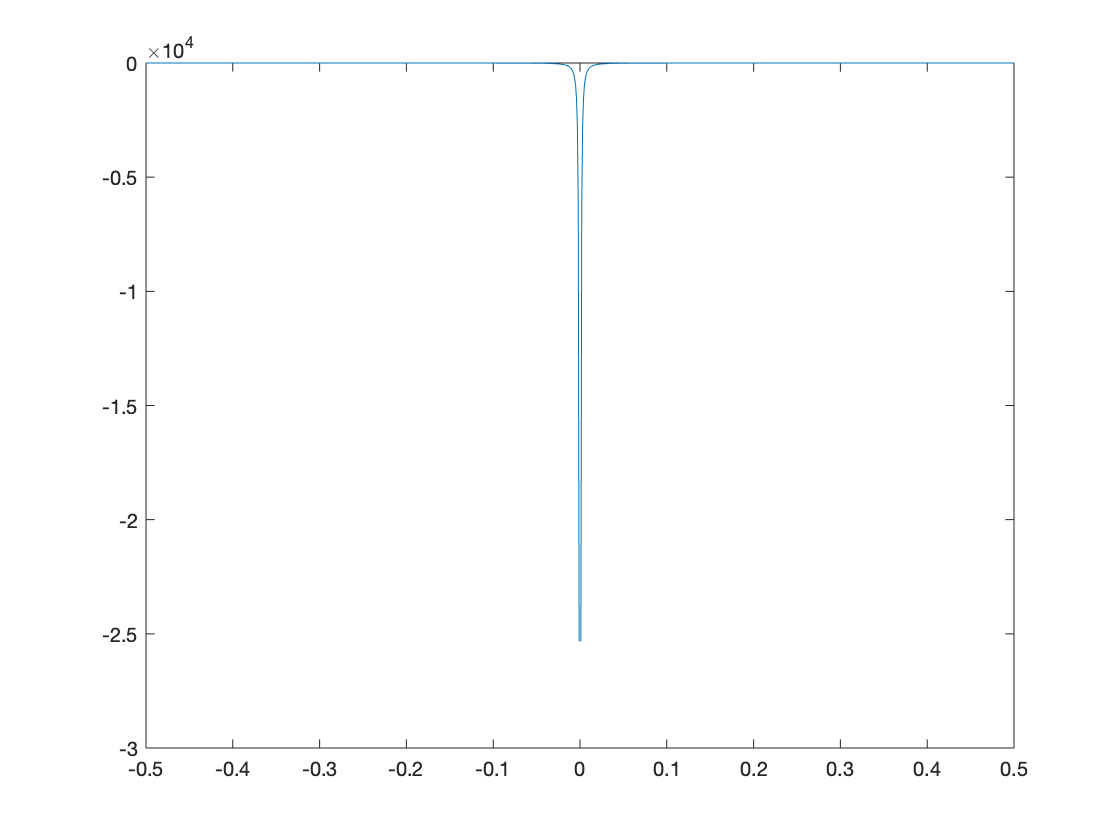

% Plot residual
omega=1; e=1; beta=1; c=1; n=2; pi=3.141592653589793;
x=0; y=linspace(-1/2,+1/2,1001);
plot(y,eval(R_E(1)))